# Statistics simulations

Fixed n_drone, variable time of simulation

% DRONE T SIMULATION %COVERED

sim_matrix = [];

directory = 'Simulation_data';

fileList = dir(fullfile(directory, 'data_sim_*.txt'));

for k = 1:length(fileList)
    fileName = fullfile(directory, fileList(k).name);
    data_sim = dlmread(fileName, ';');
    sim_matrix = [sim_matrix; data_sim];
end

sim_matrix_sorted = sort(sim_matrix)

sim_matrix_sorted =     1.0000   10.0000   12.7270
    1.0000   10.0000   17.9800
    1.0000   10.0000   26.2630
    1.0000   10.0000   33.9390
    1.0000   10.0000   43.2320
    1.0000   20.0000   44.6460
    1.0000   20.0000   47.0710
    1.0000   20.0000   48.6870
    1.0000   20.0000   52.1210
    1.0000   20.0000   52.5250


Plot the data

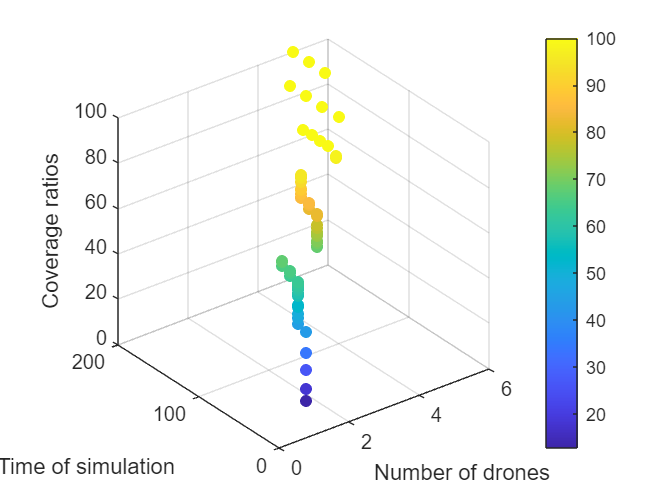

% Assumiamo che sim_matrix_sorted sia una matrice Nx3
x = sim_matrix_sorted(:, 1);
y = sim_matrix_sorted(:, 2);
z = sim_matrix_sorted(:, 3);

% Creare lo scatter plot 3D
s = scatter3(x, y, z, [], z, 'filled');
colorbar;
% Etichettare gli assi
xlabel('Number of drones');
ylabel('Time of simulation');
zlabel('Coverage ratios');
zlim([0 100]);